# Testing HDL Pulse Detector on Hardware

Copyright 2025 The MathWorks, Inc.

### Configure Parameters

pulse_detector_init;

% Board IP address
IPAddress = '192.168.1.101';

% Length of test signal
testSignalLength = 1500;

% Test signal noise scale
noiseScale = 1e-2;

% Number of samples to output after pulse detection
outputLength = 250;

% Detection threshold
threshold = 0.8;

% Location of pulse in test signal
PulseLoc = 500;

% Generate test signal
testSignal = generate_test_signal(testSignalLength,noiseScale,PulseLoc);

### Set up FPGA I/O

hw = xilinxsoc(IPAddress,'root','root');
hFPGA = fpga(hw);

WriteFrameLength = testSignalLength;
ReadFrameLength = outputLength;

pulse_detector_ipcore_hw_setup(hFPGA,WriteFrameLength,ReadFrameLength);

### Write to registers, send/receive test vectors

writePort(hFPGA, "threshold", threshold);
writePort(hFPGA, "output_length", outputLength);

writePort(hFPGA, "stream_in_data", testSignal);
[captureData, captureValid] = readPort(hFPGA, "stream_out_data");

### Display results

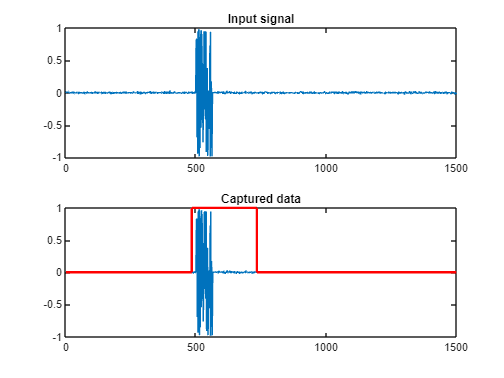

if captureValid
    figure(100); clf;
        
    % Plot input signal
    subplot(211);
    plot(real(testSignal));
    title('Input signal');

    % Show capture data positioned relative to input signal
    captureDataPos = zeros(size(testSignal),'like',testSignal);
    captureDataPos(PulseLoc-preDetectDelay-1 + (1:outputLength)) = captureData;
    captureDataValid = false(size(testSignal));
    captureDataValid(PulseLoc-preDetectDelay-1 + (1:outputLength)) = true;
    
    subplot(212);
    plot(real(captureDataPos)); hold on;
    stairs(captureDataValid,'r','LineWidth',2);
    title('Captured data');

else
    disp('Stream read timeout: no signal detected.')
end